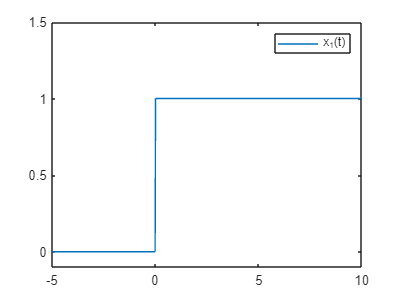

t = -5:0.01:10;
x1 = heaviside(t);
figure 
plot(t, x1)
ylim([-0.1 1.5])
legend('x_1(t)')

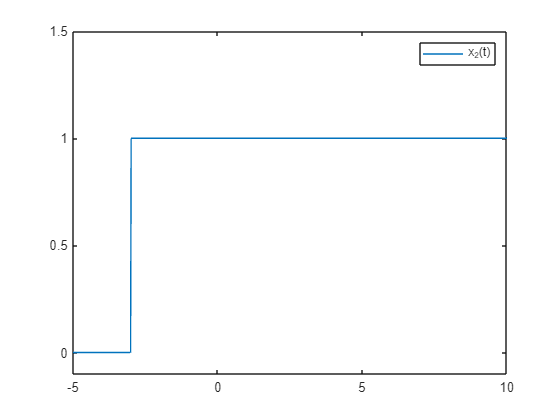

t = -5:0.01:10;
x2 = heaviside(t+3);
figure 
plot(t, x2)
ylim([-0.1 1.5])
legend('x_2(t)')

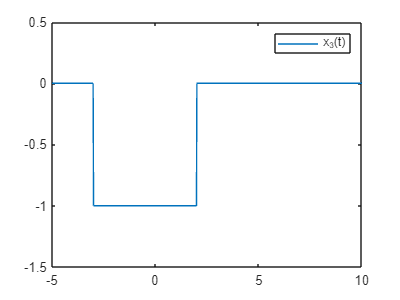

t = -5:0.01:10;
x3 = heaviside(t-2) - heaviside(t+3);
figure 
plot(t, x3)
ylim([-1.5 0.5])
legend('x_3(t)')

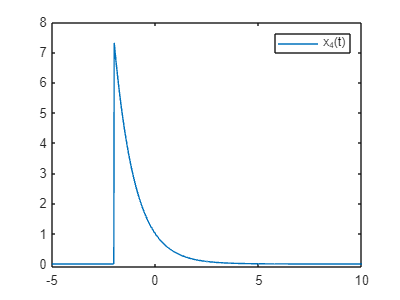

t = -5:0.01:10;
x4 = exp(-t) .* heaviside(t+2);
figure 
plot(t, x4)
ylim([-0.1 8])
legend('x_4(t)')

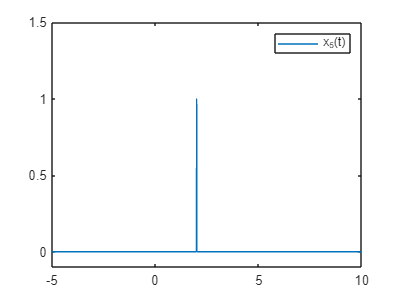

t = -5:0.01:10;
x5 = (t-2)==0;
figure
plot(t, x5)
ylim([-0.1 1.5])
legend('x_5(t)')

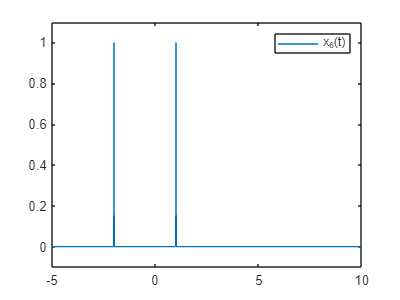

t = -5:0.01:10;
x6 = gauspuls(t-1) + gauspuls(t+2);
figure 
plot(t, x6)
ylim([-0.1 1.1])
legend('x_6(t)')

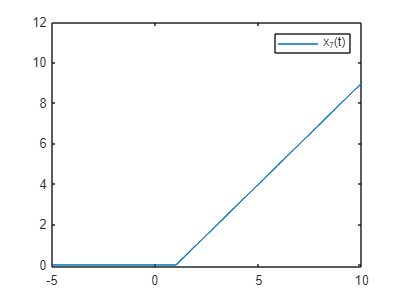

t = -5:0.01:10;
x7 = (t-1).*heaviside(t-1);
figure 
plot(t, x7)
ylim([-0.1 12])
legend('x_7(t)')

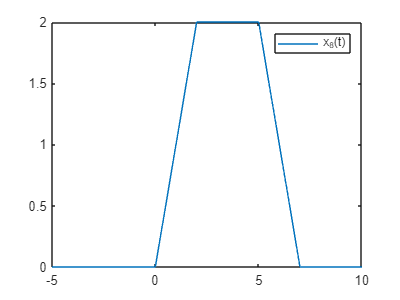

t = -5:0.01:10;
r = t.*heaviside(t);
r1 = (t-2).*heaviside(t-2);
r2 = (t-5).*heaviside(t-5);
r3 = (t-7).*heaviside(t-7);
x8 = r - r1 - r2 + r3;
figure 
plot(t, x8)
legend('x_8(t)')

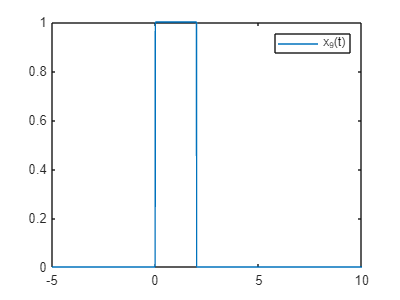

t = -5:0.01:10;
x9 = rectpuls(t-1, 2);
figure
plot(t, x9)
legend('x_9(t)')

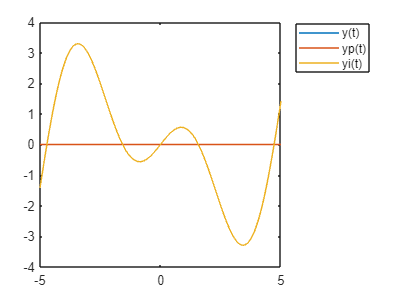

t1 = -5:0.01:5;
y = t1.*cos(t1);
yp = (y + fliplr(y))/2;
yi = (y - fliplr(y))/2;
plot(t1, y, t1, yp, t1, yi);
legend("y(t)", "yp(t)", "yi(t)", Location="bestoutside")

%Definindo o y invertido
y_inv = mean(y) - (y - mean(y));
if isequal(y, y_inv)
    tipo = "simétrico";
else
    tipo = "não simétrico";
end

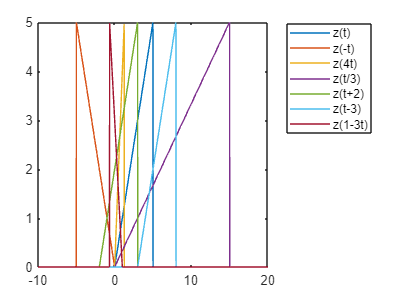

t = -10:0.01:20;
z = t.*(heaviside(t) - heaviside(t-5));
z1 = -t.*(heaviside(-t) - heaviside(-t-5));
z2 = (t*4).*(heaviside(4*t) - heaviside((4*t)-5));
z3 = (t*(1/3)).*(heaviside((1/3)*t) - heaviside(((1/3)*t)-5));
z4 = (t+2).*(heaviside(t+2) - heaviside((t+2)-5));
z5 = (t-3).*(heaviside(t-3) - heaviside((t-3)-5));
z6 = ((1-t)*3).*(heaviside(3*(1-t)) - heaviside((3*(1-t))-5));
plot(t, z, t, z1, t, z2, t, z3, t, z4, t, z5, t, z6)
legend("z(t)","z(-t)","z(4t)","z(t/3)","z(t+2)","z(t-3)","z(1-3t)", Location="bestoutside")